# **변경사항**

**2022.02.12**

- **  singlechannel, multichannel 각각 하나의 함수로 통합**

**2022.01.25**

- `readVerticalWithoutTime` 추가

# **1. readSingleChannel**

input

- `filename`: 파일 경로를 입력. xlsx, csv 파일 둘 다 가능.

- `timeColumnIdx`: 엑셀에서 데이터 파일을 열었을 때, 시간 변수가 적혀 있는 column의 위치. 예를 들어 C행에 적혀 있으면 3, F행에 적혀 있으면 6을 입력. **시간 변수가 없는 파일의 경우 0을 입력**

- `startRowIdx`: 엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 row의 위치

- `startColIdx`: 엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 column의 위치

- `sampleRate`: 시간 변수가 없는 파일의 경우 sampling frequency 값을 입력. 시간 변수가 있는 파일의 경우 nan을 입력

- `organoidNum, channelNum, month`: 관리를 위한 index, 데이터 처리에 영향을 미치지 않으므로 적절히 입력

## 예제 1. MEA data.xlsx

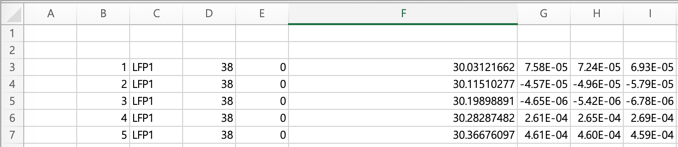

reader = channelReader();

'channelReader'은(는) 인식할 수 없는 함수 또는 변수입니다.


                                    % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate   organoidNum        channelNum     month
test_1 = reader.readSingleChannel("./data/MEA data.xlsx", 6,      3,             7,            nan,           1,              38,            1)

## 예제 2. Data 1.csv

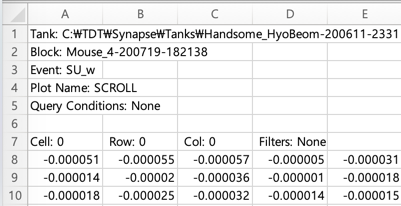

                                    % filename,     timeColumnIdx  startRowIdx  startColIdx    sampleRate     organoidNum   channelNum     month
test_2 = reader.readSingleChannel("./data/Data 1.csv",      0,       8,             1,            3152,           1,              1,         1);

## 예제 3. Data 2.csv

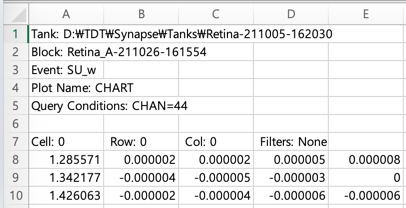

                                        % filename,    timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum    month
test_3 = reader.readSingleChannel("./data/Data 2.csv",      1,            8,             2,            nan,           1,            1,        1);

## 예제 4. 추가 data.xlsx

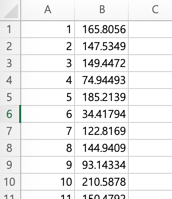

                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_4 = reader.readSingleChannel("./data/추가 data.xlsx",      0,       1,             2,            3152,           1,              1,          1);

# **2. readMultiChannelFile**

여러 채널 데이터가 포함된 파일 읽어오기

`readMultiChannelFile으로 파일 자체를 읽어옴`

- `filename`: 파일 경로를 입력. xlsx, csv 파일 둘 다 가능.

- `channelColumnIdx: `엑셀에서 데이터 파일을 열었을 때, channel 정보가 적혀 있는 column의 위치. 

- `timeColumnIdx`: 엑셀에서 데이터 파일을 열었을 때, 시간 변수가 적혀 있는 column의 위치. 예를 들어 C행에 적혀 있으면 3, F행에 적혀 있으면 6을 입력. **시간 변수가 없는 파일의 경우 0을 입력**

- `startRowIdx: `엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 row의 위치

- `startColIdx: `엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 column의 위치

- `sampleRate: `시간 변수가 없는 파일의 경우 sampling frequency 값을 입력. 시간 변수가 있는 파일의 경우 nan을 입력

`그 다음 아래의 두 가지 방법을 사용`

- `readSingleChannelFromFile: ``채널 번호를 특정하여 한 개의 채널의 데이터만 channel object로 만듦`

- `readManyChannelsFromFile: ``여러 채널 번호의 데이터를 channel object로 만듦. channel object의 리스트가 반환되며, {}로 인덱싱하면 개별 channel object가 나옴`

`1_singleunit wave.xlsx, 전체.xlsx `와 같은 포맷

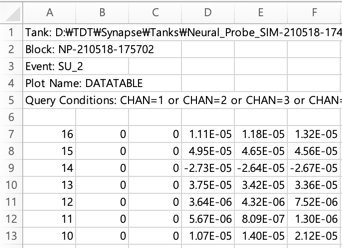     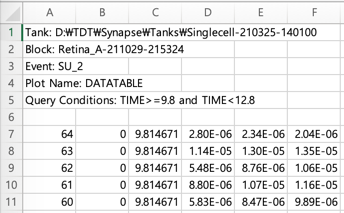

                - **7**번째 row부터 데이터 시작

                - channel number 기록되어 있음, chnnel이 여러 개 있음

                - row마다 시작 시간이 기록되어 있음

tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 51.358452초입니다.


% readSingleChannelFromFile: 원하는 channel 하나만 가져오기

%                                      organoid, channel, month 
test_5 = reader.readSingleChannelFromFile(1, 8, 1)

test_5 =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 8.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
              

% readManyChannelsFromFile: 모든 channel 다 읽어와 배열로 만들기

%                                           organoid,  array of channel numbers, month 
pixels_test6 = reader.readManyChannelsFromFile(1,              1:64,                1 );

pixel1_test6_NEW = pixels_test6_NEW{1} % 64개 채널 중 첫 번째 채널을 선택

pixel1_test6_NEW =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 1.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
    